close all

**Mohr's Circle **

**Note**: the $\tau$ axis points down.

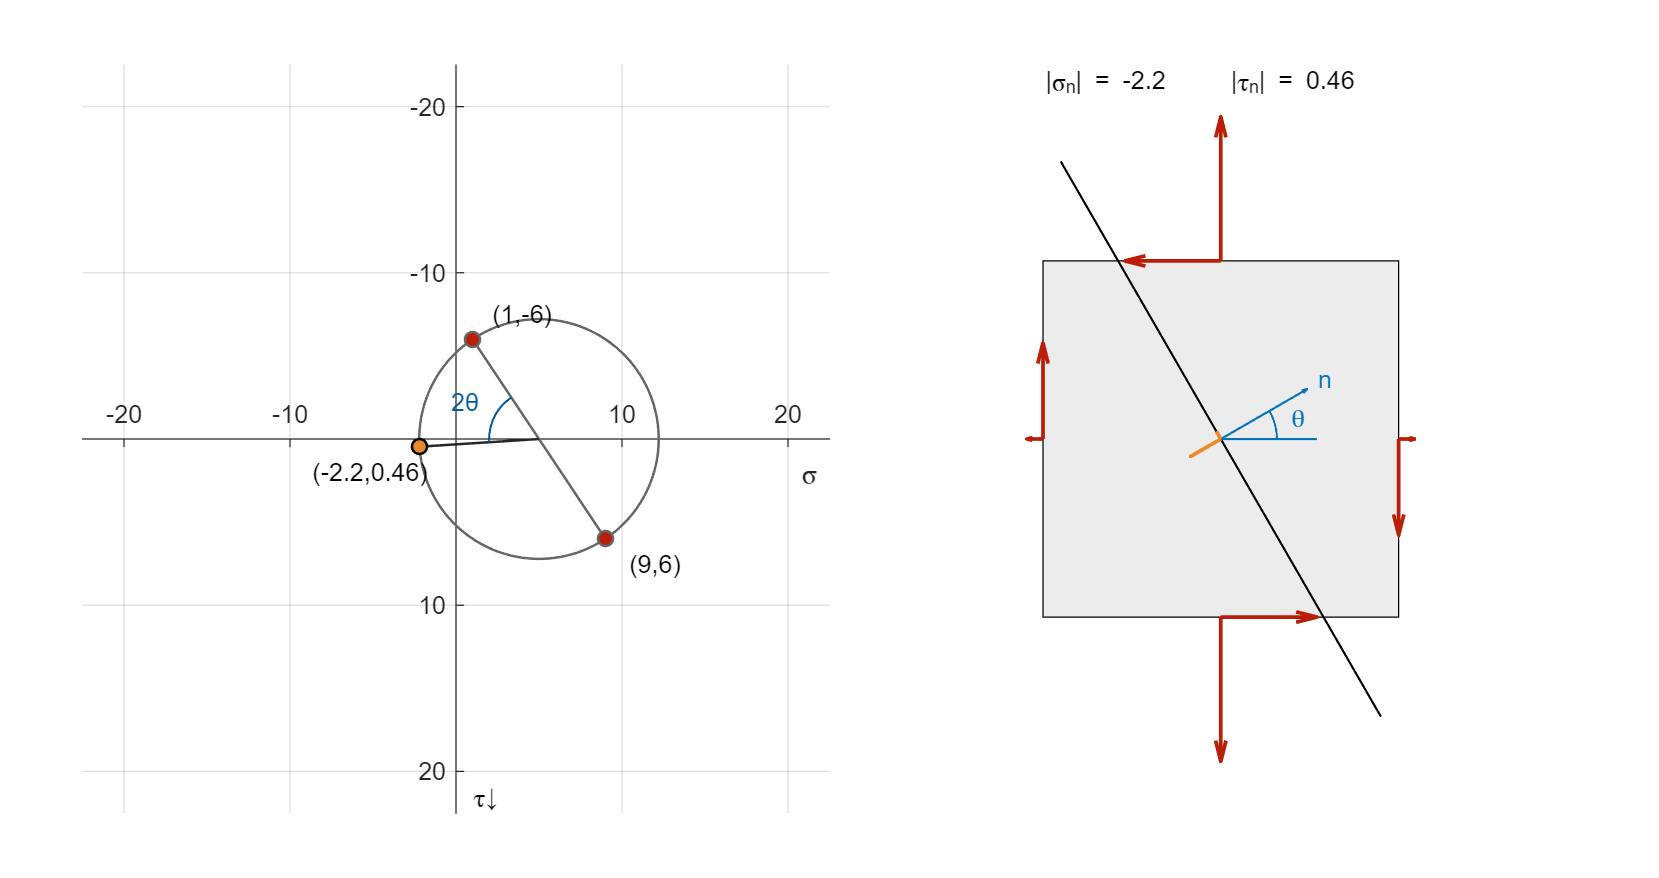

thetad =30; % Degrees
sigmax =1; % MPa
sigmay =9; % MPa
tauxy = -6; % MPa
opts.showPointLabels = true;   
opts.showTicks = true;    
opts.showPrincipleStress = false;
showMohrsCircle2D(thetad,sigmax,sigmay,tauxy,opts);

function showMohrsCircle2D(thetad,sigmax,sigmay,tauxy,opts)
    figure("outerposition",[1,1,900,475])

    subplot("position",[0.5,0.05,0.45,0.9])
    [sigman, taun] = plotStress2D(thetad,sigmax,sigmay,tauxy);

    subplot("position",[0.05,0.05,0.45,0.9])
    mohrsCircle2D(thetad,sigmax,sigmay,tauxy,sigman,taun,opts)
    
end

function mohrsCircle2D(thetad,sigmax,sigmay,tauxy,sigman,taun,opts)
    
    % Mohrs circle calculations
    R = sqrt((0.5*(sigmax - sigmay))^2 + tauxy^2);
    sigbar = 0.5*(sigmax + sigmay);

    % Settings
    circColor = [1 1 1]*0.4;
    quiverColorF = [186 30 9]/255;
    quiverColorN = [235 138 40]/255;
    sigConnectColor = [1 1 1]*0.4;
    nConnectColor = [1 1 1]*0.15;
    sigMMColor = [136 0 214]/255;
    tauMMColor = [0 121 209]/255;

    thetaAnnotationColor = [0 0.447 0.741]*0.8;

    rtheta = 5;
    circLW = 1;
    Rlim = 15;
    xyTickValues = [-20 -10 10 20];
    axLims = 1.5*Rlim*[-1 1 -1 1];
     
    % Plot calculations
    thd = linspace(0,360,500);
    xcirc = R*cosd(thd) + sigbar;
    ycirc = R*sind(thd);
        
    % Theta annotation
    phi = atan2(tauxy,sigmax-sigbar)*180/pi;

    thd = linspace(0,thetad,abs(thetad)*2);
    x_angleAnnotation = 0.6*rtheta*cosd(phi-thd*2)+sigbar;
    y_angleAnnotation = 0.6*rtheta*sind(phi-thd*2);
    x_angleText = rtheta*cosd(phi-thetad) + sigbar;
    y_angleText = rtheta*sind(phi-thetad);

    % Generate plot
    % Circle
    plot(xcirc,ycirc,"Color",circColor,"LineWidth",circLW)
    hold on
    % sigmax,sigmay,taux
    plot([sigmax sigmay],[tauxy -tauxy],"-o","Color",sigConnectColor,...
        "MarkerFaceColor",quiverColorF,"LineWidth",circLW);
    % sigman,taun
    plot([sigbar sigman],[0 taun],"Color",nConnectColor,"LineWidth",circLW)
    plot(sigman,taun,"o","Color","black",...
        "MarkerFaceColor",quiverColorN,"LineWidth",circLW);


    % Theta annotation with lines
    plot(x_angleAnnotation,y_angleAnnotation,...
        "Color",thetaAnnotationColor,"LineWidth",0.85)
    text(x_angleText, y_angleText,"2θ","Color",thetaAnnotationColor,...
        "HorizontalAlignment","center","VerticalAlignment","middle")

    % Point labels
    pointString = @(v1,v2) "(" + num2str(v1,2) + "," + num2str(v2,2) + ")";
    if(opts.showPointLabels)
        text(sigmax+3*sign(sigmax),tauxy+1.5*sign(tauxy),pointString(sigmax,tauxy),...
            "HorizontalAlignment","center","VerticalAlignment","middle");
        text(sigmay+3*sign(sigmay),-tauxy+1.5*sign(-tauxy),pointString(sigmay,-tauxy),...
            "HorizontalAlignment","center","VerticalAlignment","middle");
        text(sigman+3*sign(sigman),taun+1.5*sign(taun),pointString(sigman,taun),...
            "HorizontalAlignment","center","VerticalAlignment","middle");
    end

    % Principle stresses
    if(opts.showPrincipleStress)
        sigMM = [sigbar - R,sigbar + R];
        tauMM = [R,-R];

        plot(sigMM,[0 0],"Color",sigMMColor/2)
        plot(sigMM,[0 0],"ko","MarkerFaceColor",sigMMColor)

        plot([1 1]*sigbar, tauMM,"Color",tauMMColor/2)
        plot([1 1]*sigbar, tauMM,"ko","MarkerFaceColor",tauMMColor)

        if(opts.showPointLabels)
            text(sigMM(2)+3*sign(sigMM(2)),1,pointString(sigMM(2),0),...
                "HorizontalAlignment","center","VerticalAlignment","middle");
            text(sigMM(1)+3.5*sign(sigMM(1)),1,pointString(sigMM(1),0),...
                "HorizontalAlignment","center","VerticalAlignment","middle");
            text(sigbar+3,tauMM(1)+1*sign(tauMM(1)),pointString(0,tauMM(1)),...
                "HorizontalAlignment","center","VerticalAlignment","middle");
            text(sigbar+3,tauMM(2)+1*sign(tauMM(2)),pointString(0,tauMM(2)),...
                "HorizontalAlignment","center","VerticalAlignment","middle");
        end

    end

    hold off
    
    % Axis settings
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    axis equal
    box off
    axis(axLims)
    xticks([])
    yticks([])
    if(opts.showTicks)
        xticks(xyTickValues)
        yticks(xyTickValues)       
        grid on
    end
    set(gca,"Ydir","reverse")

    % Axis labels
    xlabel("\sigma")
    yLims = ylim;
    xLims = xlim;
    text(0.02*diff(xLims),yLims(2),"\tau↓","VerticalAlignment","baseline")
    

end




